lit = imread('checkers.jpg')

lit = 
(:,:,1) =

    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  

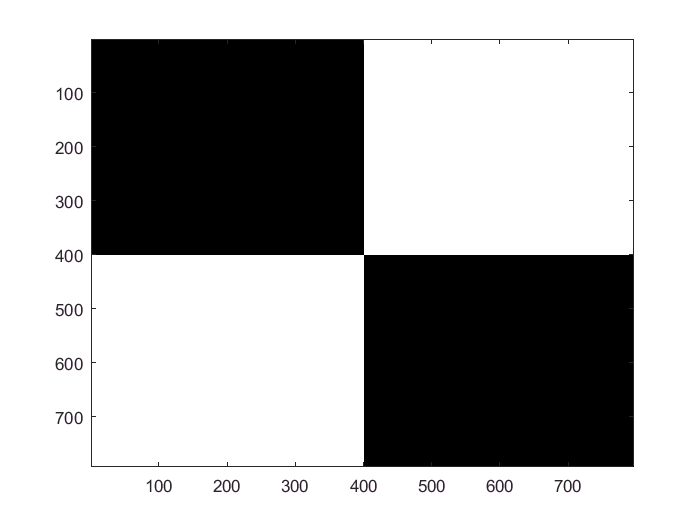

T = double(lit(:,:,1));
clf
imagesc(T); colormap('gray');

T(T == 0) = -1;
T(T == 255) = 1;
T(T >= 128) = 1;
T(abs(T) ~= 1) = -1

T =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1   

imagesc(T)

arrayT = reshape(T,631228,1);

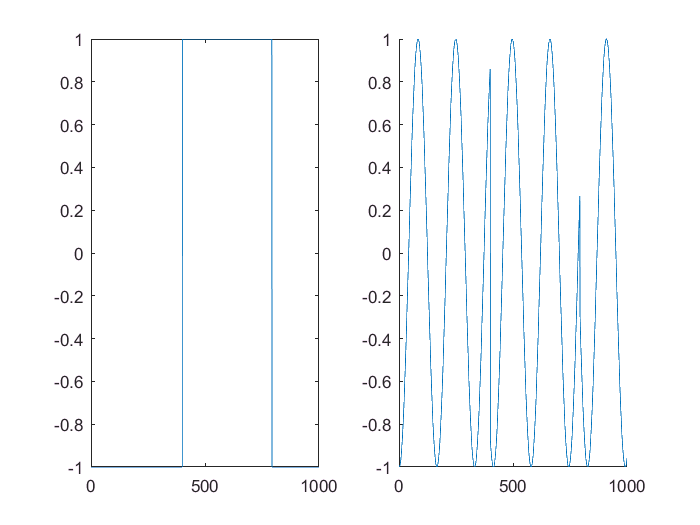

clf
subplot(1,2,1);
plot(arrayT);
xlim([0,1000])
mt = arrayT;                            %array of data
sampleTime = 10;                        %Total length of sample in time
sampleRate = 8000; %Number of samples per second
t = linspace(0,9,length(mt));           %array keeping time
w = (sampleRate/3);                     %frequency of cosine wave
c = cos(w*t);                           %array containing carrier wave
xt = mt.*c';                            %assembled signal containing carrier and signal waves
subplot(1,2,2);
hold on
plot(xt)
xlim([0,1000])
hold off

Demodulation

demod = xt.*cos(w*t)'; 
clf
% make a v e c t o r f o r the time i n di c e s
% t e c h ni c all y , t h i s i s suppsed to go from
% − i n f i n i t y t o + i n f i n i t y , but t h i s will be
% long enough
wc = .2*(w * 2* pi)/sampleRate

wc = 0.4189

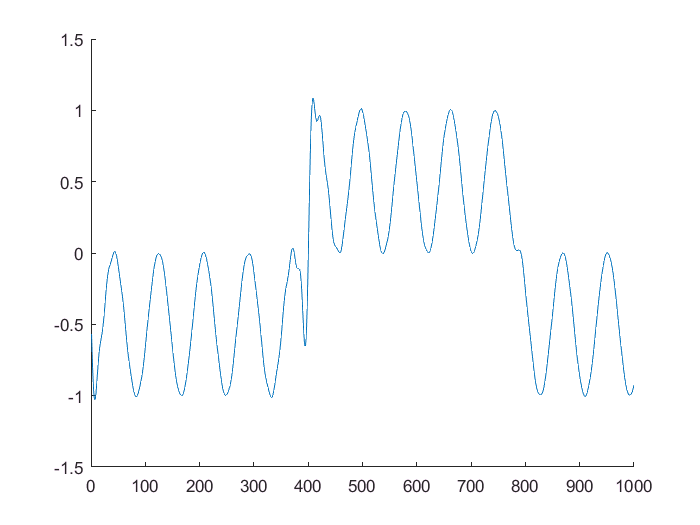

n = [-1000 : 1000] ;
% gene r a te a si n c f u n c ti o n corresponding to a LPF with c u t o f f frequency o f wc
h = wc/pi *sinc(wc*n/pi) ;
filterd = conv(demod,h,'same');
hold on
plot(filterd)
xlim([0,1000])